Import the image to be compressed

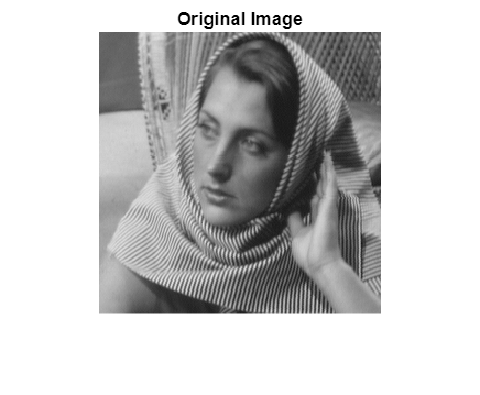

% Step 1: Preprocessing
imageFile = 'barbara256.png';
originalImg = imread(imageFile);
if size(originalImg, 3) == 3
    originalImg = rgb2gray(originalImg); % Convert to grayscale if RGB
end
originalImg = double(originalImg); % Convert to double for processing
[rows, cols] = size(originalImg);

% Display the original image
figure; imshow(uint8(originalImg)); title('Original Image');

Now we define the diffusion equation

%%%% FIXX
function diffusedImg = EED(sparseImg, region, knownPoints, lambda, sigma, numIterations)
    startRow = region(1);
    startCol = region(2);
    endRow = region(3);
    endCol = region(4);
    sparseSubImg = sparseImg(startRow:endRow, startCol:endCol);
    diffusedImg = sparseSubImg;

    % Initialize the mask of known points
    mask = zeros(size(sparseImg));
    for i = 1:size(knownPoints, 1)
        mask(knownPoints(i, 1), knownPoints(i, 2)) = 1;
    end
    submask = mask(startRow:endRow, startCol:endCol);
    
    % Pre-smooth the image
    gaussFilter = fspecial('gaussian', ceil(6 * sigma), sigma);
    smoothImg = imfilter(diffusedImg, gaussFilter, 'replicate');
    
    for iter = 1:numIterations
        % Compute smoothed gradients
        [dx, dy] = gradient(smoothImg);
        gradientMagnitude = dx.^2 + dy.^2;

        % Compute the diffusion tensor components
        diffusivity = 1 ./ sqrt(1 + gradientMagnitude / lambda^2);
        diffX = diffusivity .* dx;
        diffY = diffusivity .* dy;

        % Divergence of the diffusion tensor
        divTerm = divergence(diffX, diffY);

        % Update only unknown pixels
        diffusedImg(~submask) = diffusedImg(~submask) + divTerm(~submask);
        
        % Update the smoothed version for the next iteration
        smoothImg = imfilter(diffusedImg, gaussFilter, 'replicate');
    end

end

Now we define REED

global sparseImg;
% Recursive Subdivision with Binary Tree Encoding and Pixel Locations
function [binaryTree] = REED(img, region, threshold, maxDepth, depth, binaryTree, vertexValues, pixelLocations)
    % img           : Original image
    % region        : [startRow, startCol, endRow, endCol] of the current region
    % threshold     : Error threshold
    % maxDepth      : Maximum recursion depth
    % depth         : Current recursion depth
    % binaryTree    : Encodes the binary tree structure
    % vertexValues  : Stores pixel values of selected vertices
    % pixelLocations: Stores pixel coordinates of selected vertices
    
    global sparseImg;
    % Extract region boundaries
    startRow = region(1); startCol = region(2);
    endRow = region(3); endCol = region(4);

    % Compute midpoints for splitting
    midRow = floor((startRow + endRow) / 2);
    midCol = floor((startCol + endCol) / 2);

    % Extract the region of interest
    subImg = img(startRow:endRow, startCol:endCol);
    [h, w] = size(subImg);

    if depth == 0
        sparseImg = zeros(size(subImg));
    end

    % 0: Use EED to reconstruct the rectangle to be subdivided
    borderPoints = [startRow, startCol; startRow, midCol; startRow, endCol;
                    midRow, startCol;  midRow, endCol;
                    endRow, startCol; endRow, midCol; endRow, endCol];

    % Place the intensity values of the selected points
    for i = 1:size(borderPoints, 1)
        row = borderPoints(i, 1); % Row coordinate of the point
        col = borderPoints(i, 2); % Column coordinate of the point
        sparseImg(row, col) = img(row, col); % Copy intensity value
    end
    
    subSparseImg = sparseImg(startRow:endRow, startCol:endCol);
    mask = subSparseImg > 0.5;

    % Reconstruction Error
    lambda = 20;
    sigma = 0.8;
    num_iterations = 10;
    %diffusedImg = EED(sparseImg, region, borderPoints, lambda, sigma, numIterations);
    homogeneous_image = perform_diffusion(subSparseImg, mask, num_iterations, 'homogeneous', lambda);

    mseError = mean((homogeneous_image(:) - subImg(:)).^2);

    % Check stopping condition
    if mseError <= threshold || depth >= maxDepth
        % Add a leaf node (0) to the binary tree
        binaryTree = [binaryTree, 0]; 
        return;
    end

    % Add an internal node (1) to the binary tree
    binaryTree = [binaryTree, 1];

    % Define sub-regions
    if h > w
        subRegions = {
            [startRow, startCol, midRow, endCol], 
            [midRow, startCol, endRow, endCol], 
         };
    else
        subRegions = {
            [startRow, startCol, endRow, midCol], 
            [startRow, midCol, endRow, endCol] 
        };
    end

    % Recursively process each sub-region
    for i = 1:2
        [binaryTree] = REED(img, subRegions{i}, threshold, maxDepth, depth + 1, binaryTree, vertexValues, pixelLocations);
    end
end

% Example usage of recursive subdivision with binary tree, vertex values, and pixel locations
threshold = 20; % Error threshold for stopping
maxDepth = 12;   % Maximum recursion depth
initialRegion = [1, 1, size(originalImg, 1), size(originalImg, 2)]; % Entire image region
[binaryTree] = REED(originalImg, initialRegion, threshold, maxDepth, 0, [], [], []);


Display the selected points to be stored in the sparse image

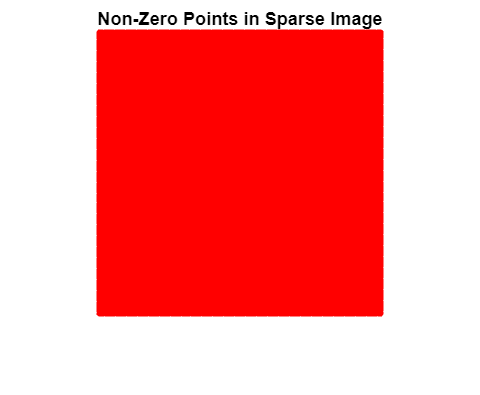

Number of non-zero points: 12545


% Function to display non-zero points in a sparse image
function displayNonZeroPoints(sparseImg)
    % Input:
    % sparseImg : Sparse image with non-zero values at specific locations
    
    % Find the non-zero points
    [rows, cols] = find(sparseImg > 0); % Rows and columns of non-zero points
    
    % Display the sparse image
    figure; imshow(uint8(sparseImg)); hold on;
    
    % Overlay the non-zero points with red markers
    plot(cols, rows, 'r.', 'MarkerSize', 10); % Plot markers at (col, row)
    title('Non-Zero Points in Sparse Image');
    
    % Display the number of non-zero points
    fprintf('Number of non-zero points: %d\n', numel(rows));
end

% Example usage
displayNonZeroPoints(sparseImg);

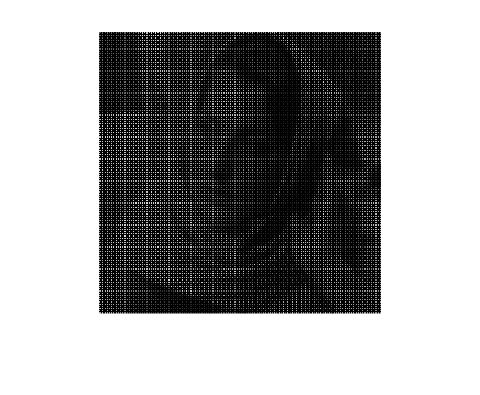

figure;imshow(uint8(sparseImg));


% Function to extract locations and vertex values from a sparse image
function [locations, vertexValues] = extractSparseImageInfo(sparseImg)
    % Input:
    % sparseImg : Sparse image with non-zero values representing vertices
    
    % Find non-zero points and their values
    [rows, cols, values] = find(sparseImg); % Rows, columns, and intensities of non-zero elements
    
    % Combine row and column indices into locations
    locations = [rows, cols]; % Nx2 array of coordinates (row, col)
    
    % Store the non-zero intensities
    vertexValues = values; % Nx1 array of intensities
    
    % Display results
    fprintf('Extracted %d locations and vertex values from the sparse image.\n', numel(values));
end

% Example usage
[locations, vertexValues] = extractSparseImageInfo(sparseImg);

Extracted 12545 locations and vertex values from the sparse image.


disp(binaryTree);

  Columns 1 through 5,461

     1     1     1     1     1     1     1     1     1     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     1     1     1     0     0     1     0     0     1     1     0     0     1     0     0     1     1     1     0     0     1     0     0     1     1     0 

fprintf('Size of Binary Tree: %d bits\n', numel(binaryTree));

Size of Binary Tree: 8191 bits


Define the encoder to encode the intensity values based on the binaryTree in an ordered manner

global BCT
BCT = binaryTree;

% Encoder Function
function [sortedLocations, intensityValues] = encoder(originalImg, region)
    global BCT;

    % Extract all locations
    locations = extractLocations(region);

    % Sort locations lexicographically (row first, then column)
    sortedLocations = sortrows(locations, [1, 2]);

    % Retrieve intensity values in sorted order
    intensityValues = arrayfun(@(r, c) originalImg(r, c), sortedLocations(:, 1), sortedLocations(:, 2));
end

% Helper Function to Extract All Locations
function locations = extractLocations(region)
    global BCT;

    % Extract current bit and pop it from the binaryTree
    currentBit = BCT(1);
    BCT(1) = []; % Remove the first bit

    % Extract region boundaries
    startRow = region(1);
    startCol = region(2);
    endRow = region(3);
    endCol = region(4);

    % If current bit is 0, extract corner and midpoint locations
    if currentBit == 0
        % Determine corner and midpoints
        midRow = floor((startRow + endRow) / 2);
        midCol = floor((startCol + endCol) / 2);

        % Locations: corners and midpoints
        locations = [
            startRow, startCol; % Top-left corner
            startRow, endCol;   % Top-right corner
            endRow, startCol;   % Bottom-left corner
            endRow, endCol;     % Bottom-right corner
            startRow, midCol;   % Top-midpoint
            midRow, startCol;   % Left-midpoint
            midRow, endCol;     % Right-midpoint
            endRow, midCol      % Bottom-midpoint
        ];
        return; % Leaf node, stop recursion
    end

    % If current bit is 1, split the region and extract recursively
    locations = [];
    midRow = floor((startRow + endRow) / 2);
    midCol = floor((startCol + endCol) / 2);

    % Determine splitting axis
    if (endRow - startRow) >= (endCol - startCol) % Split along rows
        % Top and Bottom regions
        locations = [
            extractLocations([startRow, startCol, midRow, endCol]);
            extractLocations([midRow, startCol, endRow, endCol]);
        ];
    else
        % Left and Right regions
        locations = [
            extractLocations([startRow, startCol, endRow, midCol]);
            extractLocations([startRow, midCol, endRow, endCol]);
        ];
    end
end
initial_region = [1, 1, size(originalImg, 1), size(originalImg, 2)]

initial_region =      1     1   256   256


[sortedLocations, intensityValues] = encoder(originalImg, initial_region);
sortedLocations = unique(sortedLocations, 'rows');
if (sortedLocations == sortrows(unique(locations, 'rows')))
    fprintf("Encoder successful");
else
    fprintf("Encoder not successful");
end

Encoder successful

Decoder function to get back the sparse image

global BCT
BCT = binaryTree; % THIS IS VERY STUPID, I AM CREATING A GLOBAL VARIABLE THAT I POP THINGS OUT OF, AND THEN REINITIALIZE SO I CAN USE IT AGAIN%

% Decoder Function
function [sparseImg, sortedLocations] = decoder(region, intensityValues)
    % Input:
    % imageDims      : Dimensions of the sparse image
    % sortedLocations: Sorted locations of non-zero points
    % intensityValues: Corresponding intensities of the locations

    % Initialize the sparse image
    endRow = region(3);
    endCol = region(4);
    sparseImg = zeros(endRow, endCol);

    % Extract all locations
    locations = extractLocations(region);

    % Sort locations lexicographically (row first, then column)
    sortedLocations = sortrows(locations, [1, 2]);

    % Assign intensity values to the corresponding locations
    for i = 1:size(sortedLocations, 1)
        row = sortedLocations(i, 1);
        col = sortedLocations(i, 2);
        sparseImg(row, col) = intensityValues(i);
    end
end

[decodedImage, decodedLocations] = decoder(initial_region, intensityValues);

if (decodedImage == sparseImg)
    fprintf("Decoder successful");
else
    fprintf("Decoder not successful");
end

Decoder successful

figure; imshow(uint8(decodedImage));

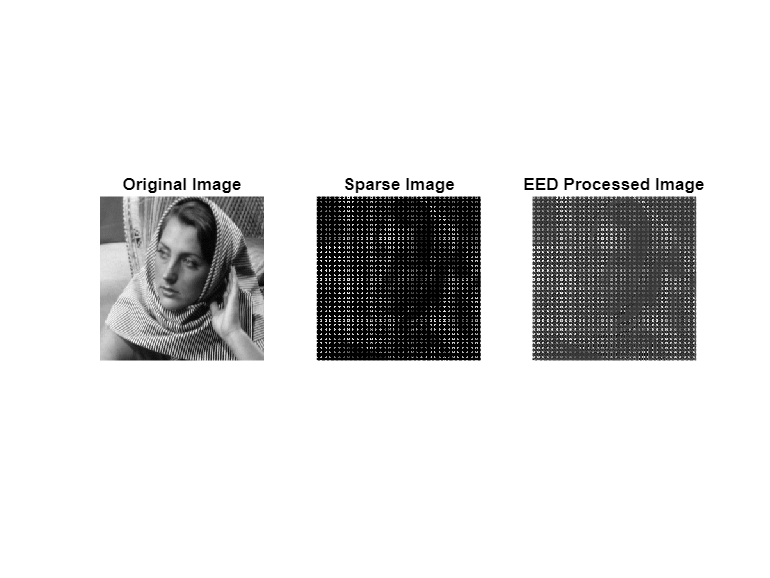

function eed_image = edge_enhancing_diffusion_sparse(sparse_image, mask, num_iterations, lambda, sigma, k)
    % Implements EED while keeping sparse points fixed
    %
    % Inputs:
    %   - sparse_image: Sparse grayscale image with known values
    %   - mask: Binary mask indicating the locations of sparse points (1 = known, 0 = unknown)
    %   - num_iterations: Number of diffusion iterations
    %   - lambda: Diffusion rate (time step, e.g., 0.1)
    %   - sigma: Standard deviation for Gaussian smoothing
    %   - k: Edge threshold for diffusivity
    %
    % Outputs:
    %   - eed_image: Processed image with fixed sparse values

    % Initialize the image with the sparse input
    eed_image = sparse_image;

    % Define Gaussian kernel for smoothing
    hsize = ceil(3 * sigma) * 2 + 1;  % Kernel size
    gaussian_filter = fspecial('gaussian', hsize, sigma);

    for t = 1:num_iterations
        % Smooth the image for computing gradients (u_sigma)
        smoothed_image = imfilter(eed_image, gaussian_filter, 'symmetric');

        % Compute gradients
        [Ix, Iy] = gradient(smoothed_image);

        % Compute diffusivity based on gradient magnitude
        g = 1 ./ (1 + (Ix.^2 + Iy.^2) / k^2);

        % Compute divergence of the diffusion tensor
        [Gx, Gy] = gradient(g);
        div_x = Gx .* Ix + g .* divergence(Ix, Iy);
        div_y = Gy .* Iy + g .* divergence(Iy, Ix);

        % Update the image using the diffusion equation
        diffusion_update = lambda * (div_x + div_y);
        eed_image = eed_image + diffusion_update;

        % Ensure sparse values remain unchanged
        eed_image(mask == 1) = sparse_image(mask == 1);
    end
end

% Create sparse image and mask
mask = sparseImg > 0.1; % 10% random pixels


% Parameters
num_iterations = 100;  % Number of iterations
lambda = 0.1;         % Time step
sigma = 1.0;          % Gaussian smoothing standard deviation
k = 20;               % Diffusivity edge threshold

% Apply EED while keeping sparse values fixed
result = edge_enhancing_diffusion_sparse(sparseImg, mask, num_iterations, lambda, sigma, k);

% Display Results
figure;
subplot(1, 3, 1); imshow(originalImg, []); title('Original Image');
subplot(1, 3, 2); imshow(sparseImg, []); title('Sparse Image');
subplot(1, 3, 3); imshow(result, []); title('EED Processed Image');

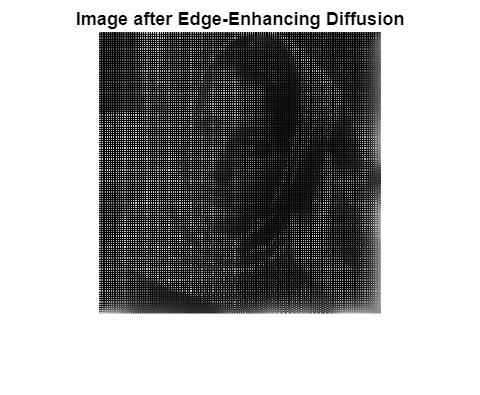


% Example usage
lambda = 20;
sigma = 0.8;
numIterations = 100;
diffusedImg = EED(sparseImg, initial_region, unique(locations, 'rows'), lambda, sigma, numIterations);
figure; imshow(uint8(diffusedImg)); title('Image after Edge-Enhancing Diffusion');

mseError = mean((diffusedImg(:) - originalImg(:)).^2)

mseError = 1.4646e+04

perform homogenous diffusion

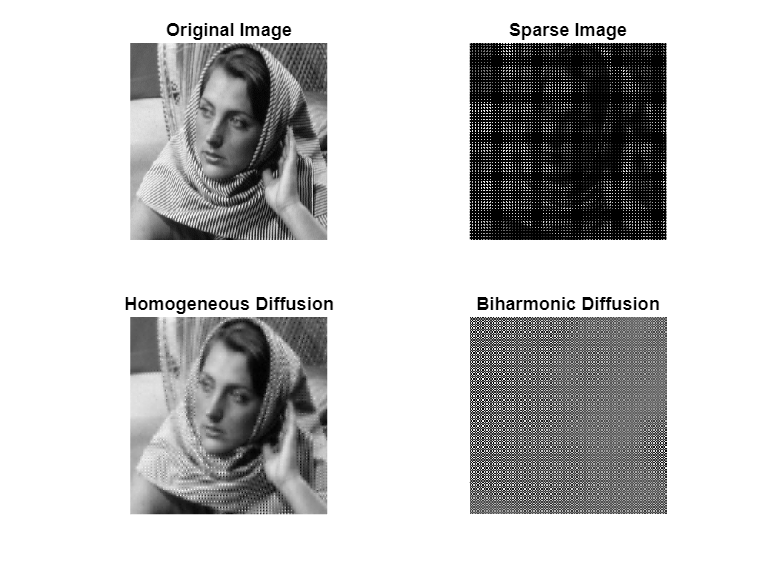

function diffused_image = perform_diffusion(sparse_image, mask, num_iterations, method, lambda)
    % Performs diffusion (Homogeneous or Biharmonic) on a sparse image.
    %
    % Inputs:
    %   - sparse_image: Sparse grayscale image with known values
    %   - mask: Binary mask indicating known values (1 = known, 0 = unknown)
    %   - num_iterations: Number of diffusion iterations
    %   - method: Diffusion method ('homogeneous' or 'biharmonic')
    %   - lambda: Diffusion rate (time step, e.g., 0.1)
    %
    % Outputs:
    %   - diffused_image: Processed image after diffusion
    
    % Initialize the image with the sparse input
    diffused_image = sparse_image;
    
    % Define Laplacian operator (second-order derivatives)
    laplacian_kernel = [0  1  0;
                        1 -4  1;
                        0  1  0];
    
    % Define Biharmonic operator (fourth-order derivatives as two Laplacians)
    biharmonic_kernel = conv2(laplacian_kernel, laplacian_kernel, 'full');
    
    % Select kernel based on method
    if strcmp(method, 'homogeneous')
        kernel = laplacian_kernel;
    elseif strcmp(method, 'biharmonic')
        kernel = biharmonic_kernel;
    else
        error('Invalid method. Use "homogeneous" or "biharmonic".');
    end

    % Perform iterative diffusion
    for t = 1:num_iterations
        % Compute the diffusion update
        diffused_update = imfilter(diffused_image, kernel, 'symmetric');
        
        % Update the image
        diffused_image = diffused_image + lambda * diffused_update;
        
        % Ensure sparse values remain unchanged
        diffused_image(mask == 1) = sparse_image(mask == 1);
    end
end


% Load example image and create sparse data
original_image = imread('barbara256.png');
if size(original_image, 3) == 3
    original_image = rgb2gray(original_image);
end
original_image = double(original_image);

% Create sparse image and mask
mask = sparseImg > 0.9; % 10% random pixels
%sparse_image = zeros(size(original_image));
%sparse_image(mask) = original_image(mask);

% Parameters
num_iterations = 100;  % Number of iterations
lambda = 0.1;         % Diffusion rate

% Perform Homogeneous Diffusion
homogeneous_image = perform_diffusion(decodedImage, mask, num_iterations, 'homogeneous', lambda);

% Perform Biharmonic Diffusion
biharmonic_image = perform_diffusion(sparseImg, mask, num_iterations, 'biharmonic', lambda);

% Display results
figure;
subplot(2, 2, 1); imshow(original_image, []); title('Original Image');
subplot(2, 2, 2); imshow(sparseImg, []); title('Sparse Image');
subplot(2, 2, 3); imshow(homogeneous_image, []); title('Homogeneous Diffusion');
subplot(2, 2, 4); imshow(biharmonic_image, []); title('Biharmonic Diffusion');

mseError = mean((homogeneous_image(:) - originalImg(:)).^2)

mseError = 224.2762